clear; clc;

N = 64;     % FFT Length
n = 0:N-1;  % Time index
k = 0:N-1;  % Frequency bin index  

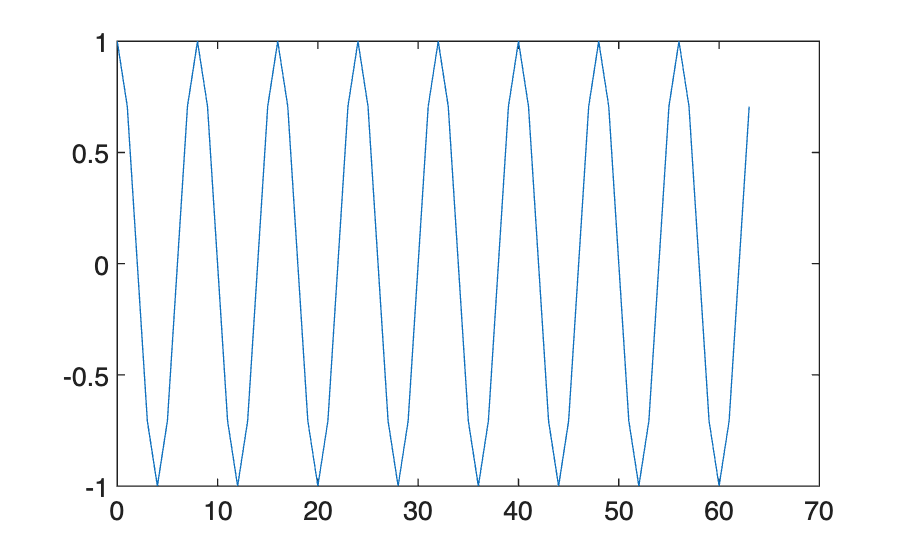

% Case A: EXACTLY periodic over N
f0 = 8/N; % 8 cycles in N
x_periodic = cos(2*pi*f0*n);
plot(n,x_periodic);

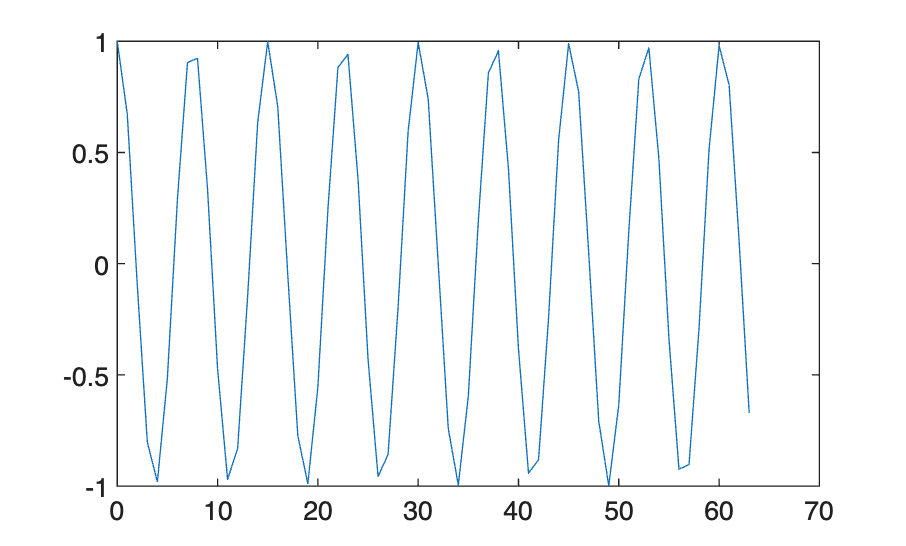

% Case B: NOT exactly periodic over N
f1 = 8.5/N;
x_trunc = cos(2*pi*f1*n);
plot(n,x_trunc);

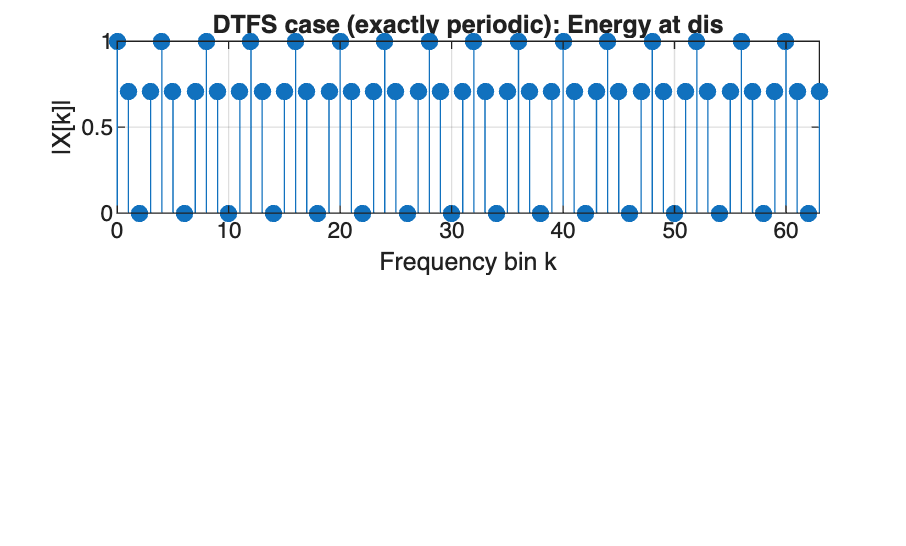

X_periodic = fft(x_periodic)/N;
X_trunc = fft(x_trunc)/N;

figure('Color','W');
subplot(2,1,1);
stem(k, abs(x_periodic), 'filled'); grid on;
title ('DTFS case (exactly periodic): Energy at dis')
xlabel('Frequency bin k'); ylabel('|X[k]|'); xlim([0 N-1]);

%% Hann window
N = 128;
n = 0:N-1;

% Non integer cycles
f0 = 13.4/N;
x = cos(2*pi*f0*n);

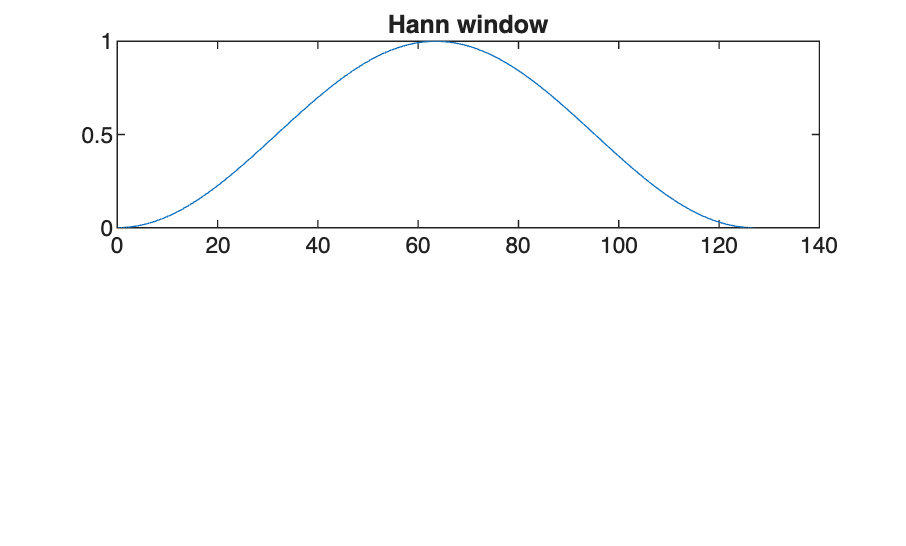

w_rect = ones(1,N);
w_hann = 0.5 - 0.5*cos(2*pi*n/(N-1)); % hann window
plot(n,w_hann); title('Hann window');


% Gain normalization
G_rect = sum(w_rect)/N;
G_hann = sum(w_hann)/N;

% Apply windows to signal
x_rect = (x .* w_rect) / G_rect;
x_hann = (x .* w_hann) / G_hann;

% Zero-Padding for smooth spectral display
M = 4096;
X_rect = fft(x_rect, M);
X_hann = fft(x_hann, M);

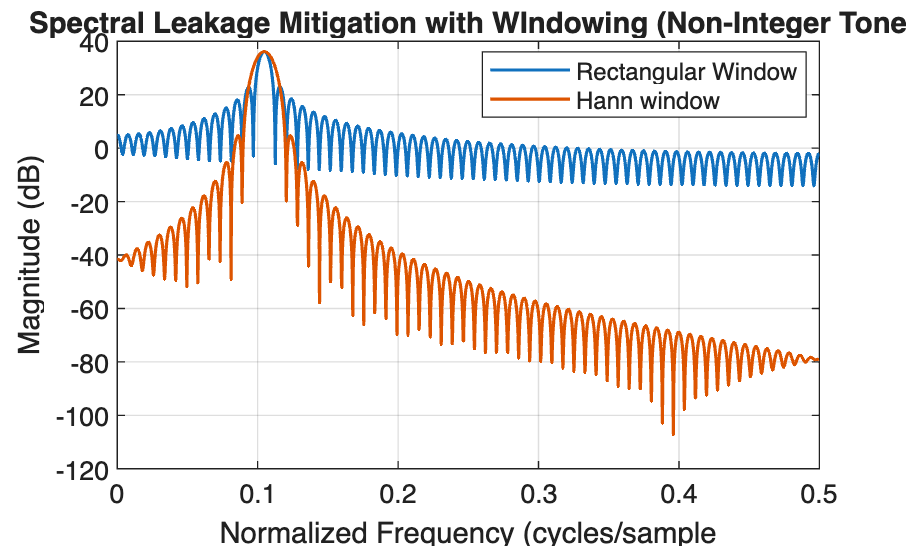

% Use single-sided spectrum
half = 1:M/2;
f = (half-1)/M; % Normalized freq

% Magnitude in dC
Rect_dB = 20*log10(abs(X_rect(half))) + eps;
Hann_dB = 20*log10(abs(X_hann(half))) + eps;

% Plot
figure('Color', 'w');
plot(f, Rect_dB, 'LineWidth', 1.2); hold on; grid on;
plot(f, Hann_dB, 'LineWidth', 1.2);
xlabel('Normalized Frequency (cycles/sample');
ylabel('Magnitude (dB)');
title('Spectral Leakage Mitigation with WIndowing (Non-Integer Tone');
legend('Rectangular Window', 'Hann window', 'Location','best');